Fs = 1e4;
t = 0:1/Fs:1;
%加速度センサの感度V/gを入力
Vag = 0.8; 
%力センサの感度V/Nを入力
Vtg = 0.12427;
x = x100hz(:,2) / Vtg;

nharm = 6;
[thd_db,harmpow,harmfreq] = thd(x,Fs,nharm);

percent_thd = 100*(10^(thd_db/20))

percent_thd = 14.9584


T = table(harmfreq,harmpow,'VariableNames',{'Frequency','Power'})

T = 6×2 table
    Frequency     Power 
    _________    _______

        100      -20.499
     200.01      -41.348
        300      -40.012
        400      -52.873
        500      -51.608
     599.99      -48.432


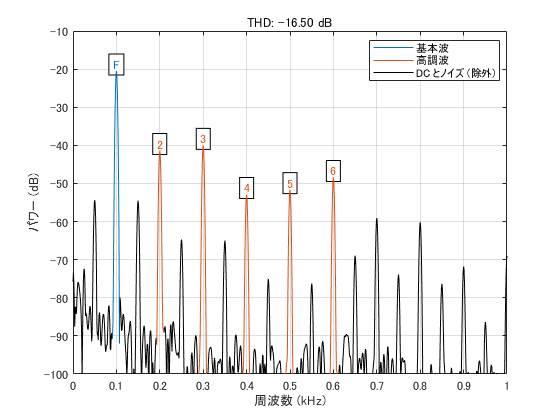


thd(x,Fs,nharm);
xlim([0 1])